% gt = g;% idx = randperm(5)
% save("id.mat","idx","c") % ,"q"
% save("/MATLAB Drive/id.mat","gs","-append")
whos("-file","id.mat") % for d

  Name      Size                Bytes  Class     Attributes

  c         2x5                 70120  cell                
  cc        2x5                214120  cell                
  cct       2x5                214120  cell                
  cg        2x5              26406800  cell                
  g         2x5              26406800  cell                
  g5        2x1               8193560  cell                
  gb        2x5              26406800  cell                
  gs        1x4              10562716  cell                
  gt        2x5              26406800  cell                
  i5h       1x500                4000  double              
  idx       1x5                    40  double              



load("/MATLAB Drive/id.mat", "c", 'idx') %O/B o/

% cg = g;
% save("/MATLAB Drive/id.mat","cg","-append")
load("/MATLAB Drive/id.mat", 'g', 'gt')

fa = 1; ci = [5 1:5-1]; cel = {c, fa, idx, ci};
addpath('/MATLAB Drive/Sim');

f = 10; fi = 1;

## Predictions:

p = pre(cel, g, fi); pt = pre(cel, gt, f);

load("/MATLAB Drive/id.mat", 'cc')

co = 5;

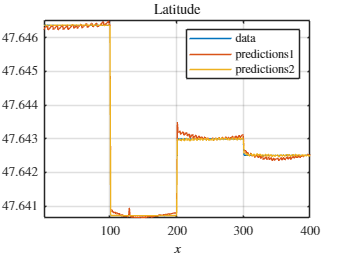

figure()
% plot(sort(cc{1,co}.Ylatitude(:)))
r = 1; t = cc{r,co};plot(t(:, end).Variables/fi);
xlabel('$x$','interpreter','latex'); axis tight
axe()
hold on;
plot(predict(g{r,co},t(:, 1:end-1 ...
    ).Variables)/fi) % ypred
plot(predict(gt{r,co},t(:, 1:end-1 ...
    ).Variables)/f)
% t = c{r,idx(ci(co))};k = t(:, end).Variables/fi;
% l = k*ones(1, 4);plot(l(:));
hold off; grid on; % xline(I)
legend({'data','predictions1','predictions2'}, ...
    'Location','Best','interpreter','latex')
title('Latitude','interpreter','latex')

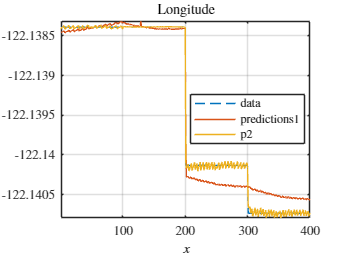

figure()
% plot(sort(cc{1,co}.Ylatitude(:)))
r = 2; t = cc{r,co};
plot(t(:, end).Variables/fi,'--');
xlabel('$x$','interpreter','latex'); axis tight
axe()
hold on; plot(predict(g{r,co},t(:, 1:end-1 ...
    ).Variables)/fi)
plot(predict(gt{r,co},t(:, 1:end-1 ...
    ).Variables)/f)
hold off; grid on; % xline(I)
legend({'data','predictions1','p2'}, ...
    'Location','Best','interpreter','latex')
title('Longitude','interpreter','latex')

load("/MATLAB Drive/id.mat", 'g', 'gt')

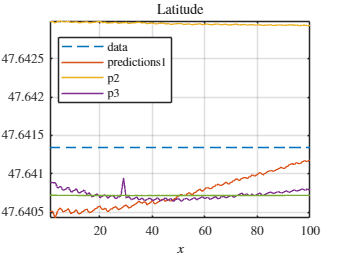

figure()
% plot(sort(cc{1,co}.Ylatitude(:)))
r = 1; co = 5; ci = [5 1:5-1];t = c{r,idx(ci(co))};
plot(t(:, end).Variables/fi,'--');
xlabel('$x$','interpreter','latex'); axis tight
axe()
hold on; plot(p(:, r, co)); plot(pt(:, r, co));
t = cc{r, co}; s = 101:200;
plot(predict(g{r,co},t(s, 1:end-1 ...
    ).Variables)/fi)
plot(predict(gt{r,co},t(s, 1:end-1 ...
    ).Variables)/f)
hold off; grid on; % xline(I)
legend({'data','predictions1','p2','p3'}, ...
    'Location','Best','interpreter','latex')
title('Latitude','interpreter','latex')

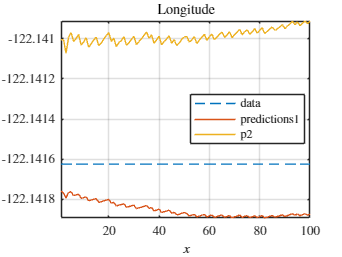

figure()
% plot(sort(cc{1,co}.Ylatitude(:)))
r = 2; t = c{r,idx(ci(co))};
plot(t(:, end).Variables/fi,'--');
xlabel('$x$','interpreter','latex'); axis tight
axe()
hold on; plot(predict(g{r,co},t(:, 1:end-1 ...
    ).Variables)/fi)
plot(predict(gt{r,co},t(:, 1:end-1 ...
    ).Variables)/f)
hold off; grid on; % xline(I)
legend({'data','predictions1','p2'}, ...
    'Location','Best','interpreter','latex')
title('Longitude','interpreter','latex')

## d

[d11m, d12m] = dis(cel, p);
[d21m, d22m] = dis(cel, pt);

[m(2),I] = max(d1km(:)*1000);

table([m(1),i]', [m(2),I]','VariableNames',{...
    'Min','Max'},'RowNames',{'Distance(m)';...
    'Position'})

ans = 2x2 table
                    Min       Max  
                   ______    ______

    Distance(m)    279.71    335.14
    Position          100       101


# D table:

m1 = dtl(d11m); m1'

ans =   208.7813   98.0000  280.9062    1.0000
  560.3561  100.0000  691.2287    1.0000
   29.8208    1.0000   69.5777  100.0000
   70.3248   98.0000   70.3383    1.0000
   25.7853  100.0000  102.8744    3.0000


mt = dtl(d21m); mt'

ans =   123.1473   98.0000  186.8875    1.0000
  371.9470  100.0000  411.0795    1.0000
   70.2413    5.0000  111.7496    1.0000
   70.2527    5.0000   70.2549   99.0000
  183.2892   82.0000  189.6819    5.0000


% d1km(1:5,:)
% m = zeros(2, 5);
% for co = 1:5
%     m(1, co) = min(...
%         d1km(:, co)*1000);
%     m(2, co) = max(...
%         d1km(:, co)*1000);
% end

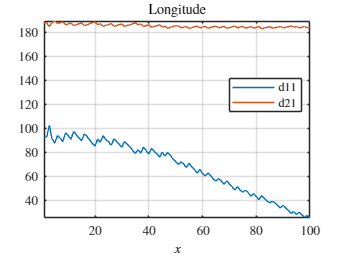

figure()
co = 5; plot(d11m(:, co));
% plot(sort(cc{2,co}.Ylongitude(:)));
axis tight; xlabel('$x$','interpreter','latex')
axe()
hold on
% plot(sort(p(:,2))*f)
plot(d21m(:, co))
hold off;
grid on; % xline(I)
legend({'d11','d21'}, ...
    'Location','Best','interpreter','latex')
title('Longitude','interpreter','latex')

m'% reshape(m,4,5)'% table('Min, 'm')

ans =   208.7813   98.0000  280.9062    1.0000
  560.3561  100.0000  691.2287    1.0000
   29.8208    1.0000   69.5777  100.0000
   70.3248   98.0000   70.3383    1.0000
   25.7853  100.0000  102.8744    3.0000


sympref('FloatingPointOutput',true);

i = 1; t = cc{1,1}; tt = cc{2,1};t(m(4,i), :)

ans = 1x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     222.54      47.637      -122.14      349       215       47.641  


tt(m(4,i),:)

ans = 1x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylongitude
    ________    ________    _________    ______    ______    __________

     222.54      47.637      -122.14      349       215       -122.14  


latex(sym([(1:5)' m']))

ans = '\left(\begin{array}{ccc} 1 & 224.2659 & 290.7717\\ 2 & 245.5756 & 528.1451\\ 3 & 17.6752 & 60.6458\\ 4 & 18.0240 & 76.8259\\ 5 & 140.5769 & 215.4309 \end{array}\right)'

[c{1,idx(5)}.Ylatitude(1:5) ...
    c{2,idx(5)}.Ylongitude(1:5)]

ans =    47.6464 -122.1384
   47.6464 -122.1384
   47.6464 -122.1384
   47.6464 -122.1384
   47.6464 -122.1384


k = zeros(5,2);
for co = 1:5
    k(co, :) = [c{1,co}.Ylatitude(5) c{2, ...
        co}.Ylongitude(5)];
end
k

k =    47.6425 -122.1407
   47.6413 -122.1416
   47.6407 -122.1384
   47.6464 -122.1384
   47.6430 -122.1401


ci = [5 1:5-1]

ci =      5     1     2     3     4


for co = 1:5
    [cc{1,co}.Ylatitude(1:100:end) ...
    cc{2,co}.Ylongitude(1:100:end);c{1, ...
        idx(ci(co))}.Ylatitude(5) ...
    c{2,idx(ci(co))}.Ylongitude(5); ...
    p(5,1,co) p(5, 2,co)]
end

ans =    47.6407 -122.1384
   47.6430 -122.1401
   47.6425 -122.1407
   47.6413 -122.1416
   47.6464 -122.1384
   47.6440 -122.1391


ans =    47.6430 -122.1401
   47.6425 -122.1407
   47.6413 -122.1416
   47.6464 -122.1384
   47.6407 -122.1384
   47.6463 -122.1422


ans =    47.6425 -122.1407
   47.6413 -122.1416
   47.6464 -122.1384
   47.6407 -122.1384
   47.6430 -122.1401
   47.6425 -122.1407


ans =    47.6413 -122.1416
   47.6464 -122.1384
   47.6407 -122.1384
   47.6430 -122.1401
   47.6425 -122.1407
   47.6430 -122.1401


ans =    47.6464 -122.1384
   47.6407 -122.1384
   47.6430 -122.1401
   47.6425 -122.1407
   47.6413 -122.1416
   47.6406 -122.1418


figure();
plot(tllts(:, ...
    1:end-1).Variables);
axis tight % [0 1050 0 30]
xlabel('x')
ylabel('y')
hold on;
plot(ypredlo);
hold off;
grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Altitude')

function m = dtl(d1m)
    m = zeros(4, 5);
    for co = 1:5
        [m(1, co), m(2, co)] = min(d1m(:, co));
        [m(3, co), m(4, co)] = max(d1m(:, co));
    end
end

function [d1km, d2km] = dis(cel, p)
    tr = 100*cel{2}+1; idx = cel{3}; % c/c
    ci = cel{4};
    d1km = zeros(tr-1, 5); d2km = d1km; c = cel{1};
    for co = 1:5
        for i = 1:tr-1
            [d1km(i, co), d2km(i, co)] = ...
                lldistkm(...
                [c{1,idx(ci(co))}.Ylatitude(i...
                ) c{2,idx(ci(co))}.Ylongitude(i...
                )], [p(i,1,co) p(i,2,co)]);
        end
    end
    d1km = d1km*1000; d2km = d2km*1000; % m
end

function p = pre(cel, g, te)
    p = zeros(100*cel{2},2,5); ci = cel{4};
    c = cel{1}; idx = cel{3};
    for r = 1:2
        for co = 1:5 % ypred
            t = c{r,idx(ci(co))}; % cc
            p(:,r,co) = predict(g{r,co},t(:,...
                1: end-1).Variables)/te;
        end % cg, gb
    end
end

function axe()
    axes = gca;
    axes.XAxis.TickLabelInterpreter = 'latex';
    axes.YAxis.TickLabelInterpreter = 'latex';
end